# Tutorial 3: Using +microstate toolbox for simulations and group-level analysis

This tutorial will simulate and analyse an experiment with 20 participants who each underwent two resting-state scans in two experimental conditions. In one condition, the microstates have a random-walk property, and in the 2nd the microstates have Markov property. This is described in more detail in section 3.3 of the toolbox manuscript. The second half of this script will treat the simulations as real data and perform microstate analysis, demonstrating significant differences between properties of the microstate sequences between conditions.

This section will reproduce the analysis described in section 3.3 of the toolbox manuscript [1]. 

References:

[1] Tait and Zhang (2021) bioRxiv 2021.07.13.452193; doi: [https://doi.org/10.1101/2021.07.13.452193](https://doi.org/10.1101/2021.07.13.452193) 

### Simulate data

This section of the script simulates the data. Firstly, we assume that each individual's microstate maps are some group level maps plus some noise and some arbitrary source flipping. The latter is a result of source-reconstruction/parcellation, and can influence group-level microstate estimation so must be accounted for. The generalized k-means algorithm accounts for this source flipping by taking the absolute value for data with modality 'source'.

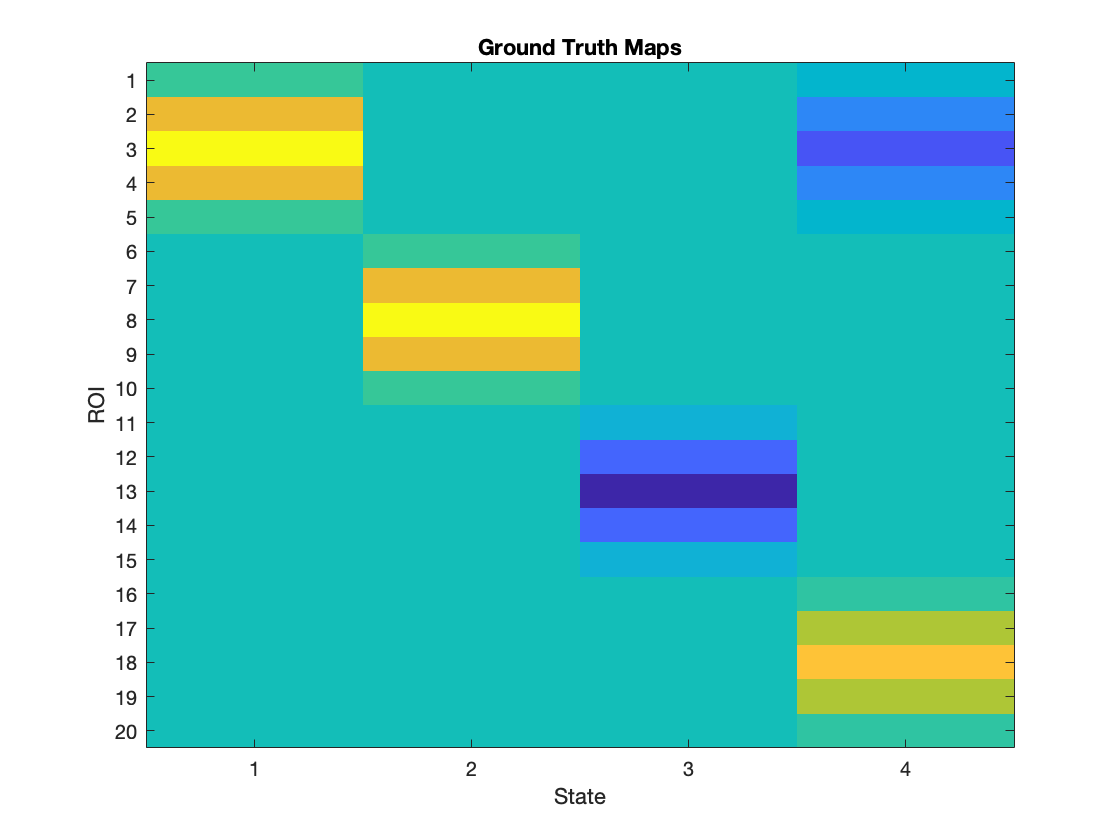

% Make group level maps and plot
clear, clc, close all;
rng('default') % for reproducibility
GroupMaps = makeGroupMaps ; % this function is supplied in the example3 folder
imagesc(GroupMaps) % plot the group maps
set(gca,'XTick',1:4,'YTick',1:20), xlabel('State'), ylabel('ROI') % label axes
title('Ground Truth Maps') % give a title

Next, we perform the simulations. Firstly, this involves initializing a cohort object in which to store the simulated data. Then, we loop over our 20 participants. For each participant, we: 

- Generate the participant's individual map by adding noise and arbitrarily flipping the sign of ROIs.

- Simulate the first scan (random-walk sequence) under the default simulation settings 

- Add the first simulated scan to a microstate individual object and store it in the cohort object 

- Obtain a Markov matrix from the simulated sequence, and use this matrix to simulate the second scan (Markovian sequence) 

- Add the second simulated scan to a microstate individual object and store it in the cohort object

% Initialize a microstate cohort
cohort_sim = microstate.cohort ;
numParticipants = 20 ;
for i = 1:numParticipants % loop over participants

    % Add individual noise to maps
    IndividualMap = GroupMaps+0.02*randn(size(GroupMaps)) ; % Add noise
    IndividualMap = IndividualMap.*sign(randn(size(IndividualMap))) ; % Simulate source flipping
    IndividualMap = IndividualMap./vecnorm(IndividualMap) ; % Ensure maps have uniform vecnorm

    % Simulate condition 1: randomwalk
    fprintf('Participant %d of %d (random walk): ',i,numParticipants) ;
    simRW = microstate.individual; % initialize the simulation
    simRW.maps = IndividualMap ; % add the individual maps
    simRW = simRW.simulate ; % simulate some data using default settings

    % Since we want to treat the simulated data as if it were experimental,
    % make a new individual storing only the data (not the ground truth
    % maps or sequences).
    msRW = microstate.individual(simRW.data,'source',simRW.time) ;

    % Simulate condition 2: markov
    fprintf('Participant %d of %d (Markov): ',i,numParticipants) ;
    simRW = simRW.stats_markov ; % get markov matrix from our Random walk simulation
    simM = microstate.individual; % initialize a new simulation
    simM.maps = IndividualMap ; % add individual maps
    simM.stats.markov.matrix = simRW.stats.markov.matrix ; % add markov matrix
    simM = simM.simulate ; % will simulate markov, since we specified
                           % a markov matrix

    % Make an individual to store the data in
    msM = microstate.individual(simM.data,'source',simRW.time) ;

    % add both to cohort
    % input 1 is the individual object. input 2 is a label for the cohort,
    % here we will use 'rw' for randomwalk and 'm' for markov, but these
    % can be anything. input 3 tells us how to store the data.
    % Setting it to 1 tells us to store all of the data. For memory, by
    % default data is not stored. With this input, we can also store a
    % percent of the data or X GFP peaks.
    cohort_sim = cohort_sim.add_individuals(msRW,'Random Walk',1) ;
    cohort_sim = cohort_sim.add_individuals(msM,'Markov',1) ;

end

Participant 1 of 20 (random walk): 

Simulating: 100.00 percent


Participant 1 of 20 (Markov): 

Simulating: 100.00 percent


Participant 2 of 20 (random walk): 

Simulating: 100.00 percent


Participant 2 of 20 (Markov): 

Simulating: 100.00 percent


Participant 3 of 20 (random walk): 

Simulating: 100.00 percent


Participant 3 of 20 (Markov): 

Simulating: 100.00 percent


Participant 4 of 20 (random walk): 

Simulating: 100.00 percent


Participant 4 of 20 (Markov): 

Simulating: 100.00 percent


Participant 5 of 20 (random walk): 

Simulating: 100.00 percent


Participant 5 of 20 (Markov): 

Simulating: 100.00 percent


Participant 6 of 20 (random walk): 

Simulating: 100.00 percent


Participant 6 of 20 (Markov): 

Simulating: 100.00 percent


Participant 7 of 20 (random walk): 

Simulating: 100.00 percent


Participant 7 of 20 (Markov): 

Simulating: 100.00 percent


Participant 8 of 20 (random walk): 

Simulating: 100.00 percent


Participant 8 of 20 (Markov): 

Simulating: 100.00 percent


Participant 9 of 20 (random walk): 

Simulating: 100.00 percent


Participant 9 of 20 (Markov): 

Simulating: 100.00 percent


Participant 10 of 20 (random walk): 

Simulating: 100.00 percent


Participant 10 of 20 (Markov): 

Simulating: 100.00 percent


Participant 11 of 20 (random walk): 

Simulating: 100.00 percent


Participant 11 of 20 (Markov): 

Simulating: 100.00 percent


Participant 12 of 20 (random walk): 

Simulating: 100.00 percent


Participant 12 of 20 (Markov): 

Simulating: 100.00 percent


Participant 13 of 20 (random walk): 

Simulating: 100.00 percent


Participant 13 of 20 (Markov): 

Simulating: 100.00 percent


Participant 14 of 20 (random walk): 

Simulating: 100.00 percent


Participant 14 of 20 (Markov): 

Simulating: 100.00 percent


Participant 15 of 20 (random walk): 

Simulating: 100.00 percent


Participant 15 of 20 (Markov): 

Simulating: 100.00 percent


Participant 16 of 20 (random walk): 

Simulating: 100.00 percent


Participant 16 of 20 (Markov): 

Simulating: 100.00 percent


Participant 17 of 20 (random walk): 

Simulating: 100.00 percent


Participant 17 of 20 (Markov): 

Simulating: 100.00 percent


Participant 18 of 20 (random walk): 

Simulating: 100.00 percent


Participant 18 of 20 (Markov): 

Simulating: 100.00 percent


Participant 19 of 20 (random walk): 

Simulating: 100.00 percent


Participant 19 of 20 (Markov): 

Simulating: 100.00 percent


Participant 20 of 20 (random walk): 

Simulating: 100.00 percent


Participant 20 of 20 (Markov): 

Simulating: 100.00 percent


### Group-level k-means clustering

In this section, we treat the simulated data as though it were real source-reconstructed M/EEG data and perform microstate analysis. Importantly, our cohort object does not contain the ground truth maps or sequences, so much like real data we must estimate these with a microstate algorithm. We will therefore cluster the data to estimate group-level maps.

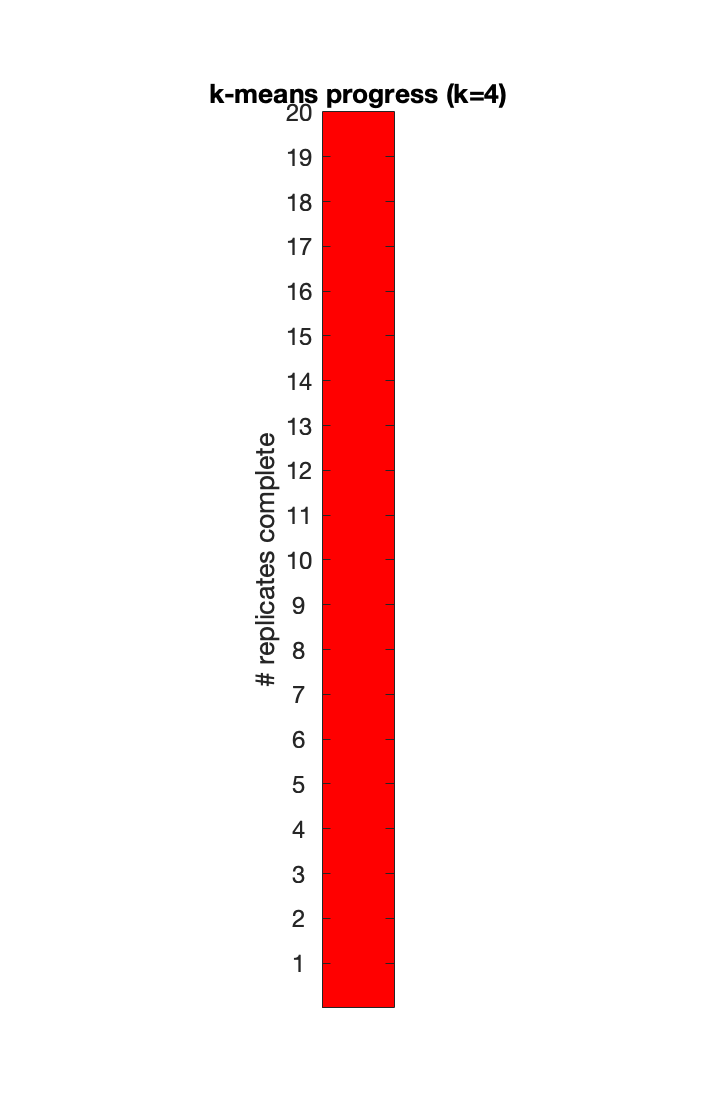

% Clear everything except the data cohort so that we have no knowledge of ground truths
clearvars -except cohort_sim

% Preprocess - bandpass filter 1-30 Hz
cohort_sim = cohort_sim.ind_preprocess_filter(1,30) ;

% Cluster to get maps. Here we will specify 4 maps, but we can call
% cluster_globalkoptimum to find optimum number of maps if we do not know
% the number of maps.
cohort_sim = cohort_sim.cluster_global(4) ;

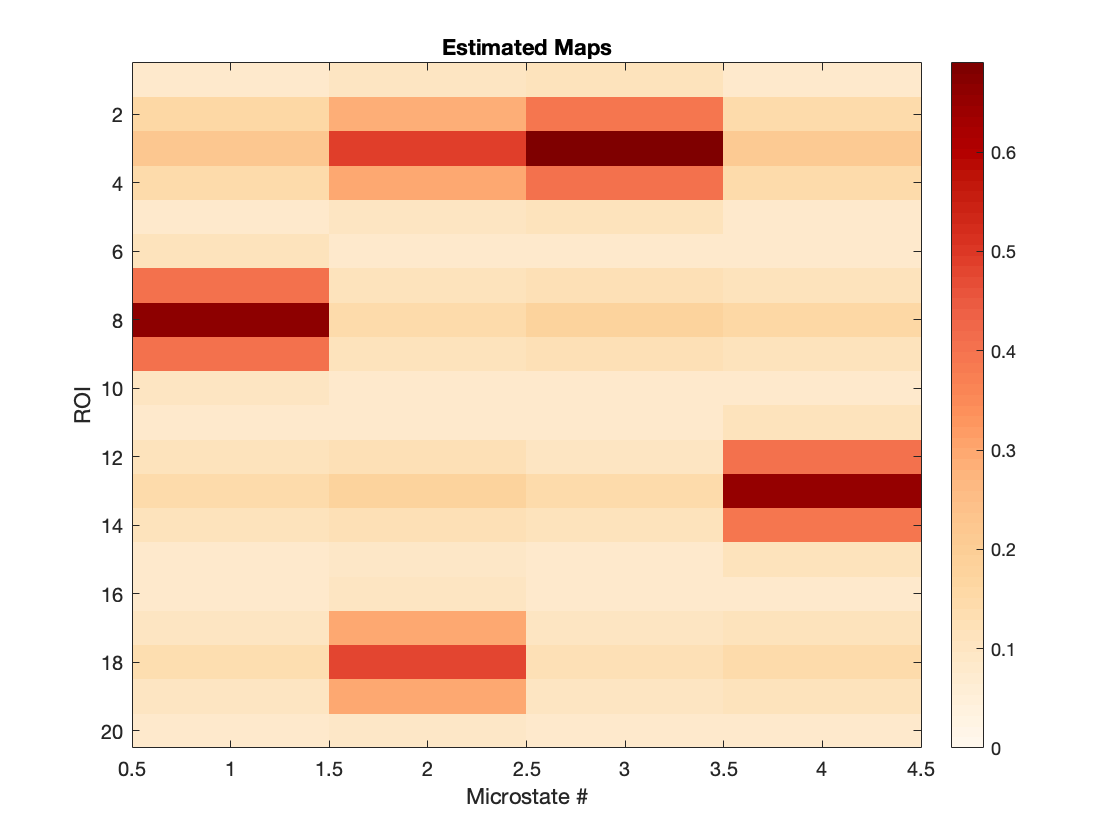

figure
cohort_sim.plot('globalmaps')
title('Estimated Maps')

The order differs, but it is clear the clustered maps reflect the ground-truth maps. Let us now align these estimated maps with the original group maps using a template matching algorithm and calculate similarity in order to quantify the accuracy of the estimation.

% Re-make the ground truth group maps 
GroupMaps = makeGroupMaps ;

% Align the estimated maps to the ground truth maps
[orderedMaps,mapSimilarity] = microstate.functions.align_maps2template(cohort_sim.globalmaps,abs(GroupMaps),'source') ; 

% Display the similarity values
fprintf('Map similarity = ')

Map similarity = 

disp(mapSimilarity)

    0.9051    0.8803    0.8804    0.9239



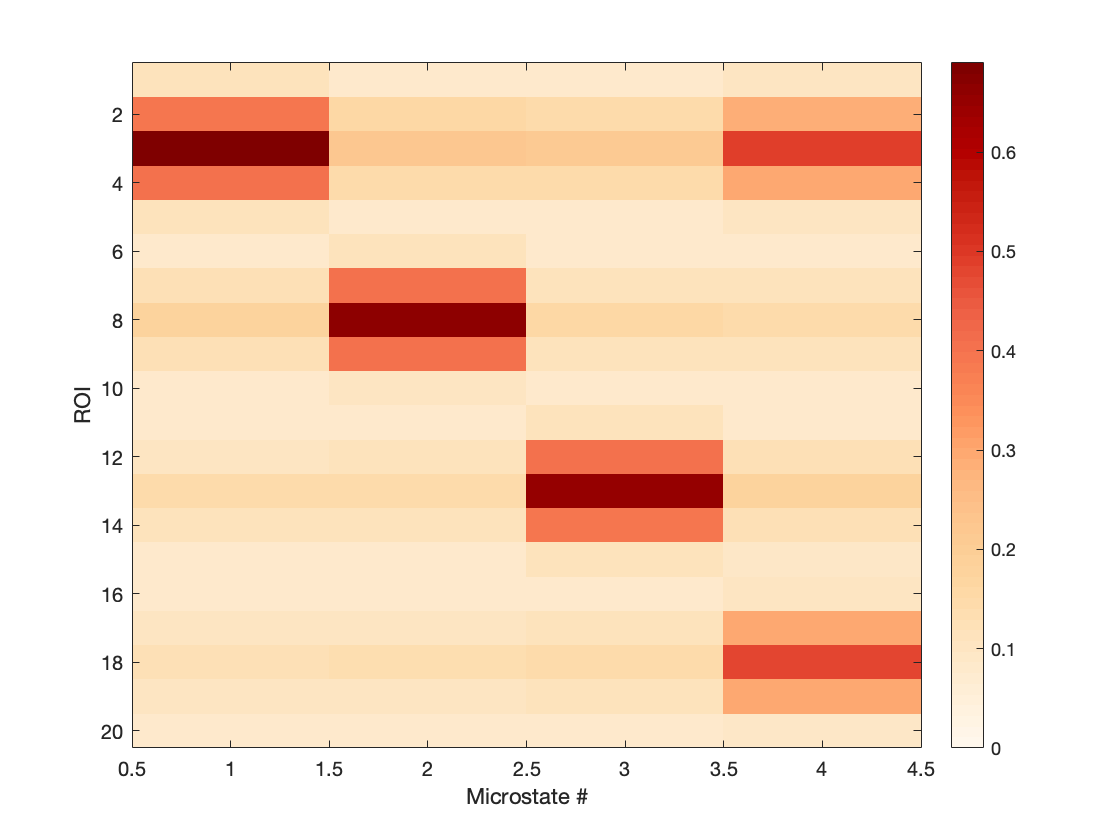


% Plot the maps in the same order as the ground truth maps
figure
ind_plot_alignedmaps = microstate.individual ; 
ind_plot_alignedmaps.maps = orderedMaps ; 
ind_plot_alignedmaps.modality = 'source' ; 
ind_plot_alignedmaps.plot('maps') ; 

### Group-level stats

Now that we have performed microstate analysis, we should form some hypothesis to test. In this case, we use the hypothesis that the estimated microstate sequences from cohort #2 (the Markovian ground truth sequences) will have fewer long-range correlations than the estimated sequences from cohort #1. Below, we calculate and plot the Hurst exponents. Because of the within-subject design (each participant had one scan for each condition), we use a paired test (Wilcoxon sign-rank test) to compare the Hurst exponents of the two conditions.

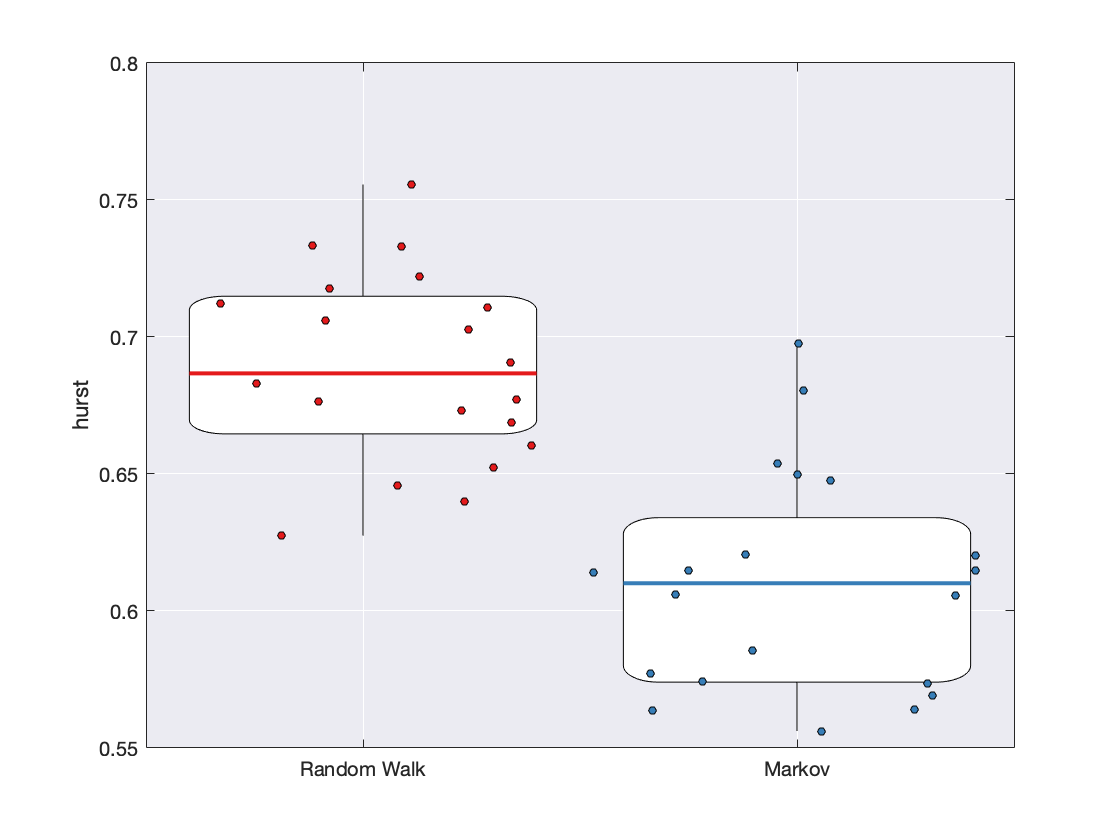

% Backfit global maps to the data
cohort_sim = cohort_sim.cluster_globalmaps2individual ;

% Now, test the hypothesis that cohort #2 has lower hurst exponent
cohort_sim = cohort_sim.ind_stats_hurst ; % any function starting with ind_ just loops over
   % individuals, i.e. this is equivalent to stats_hurst for each individual
cohort_sim = cohort_sim.cohort_stats ; % get stats per each cohort

% Plot hurst exponent
figure
cohort_sim.plot('hurst') ;

p = signrank(cohort_sim.stats(1).hurst, cohort_sim.stats(2).hurst)

p = 2.1908e-04